## Compute autospectrum of Del Mar alongshore surface current

load DelMar_data
x = v(1,:)';
dt = t(2)-t(1);   %sample period in days % set units here by choosing days
N = length(t);


## Take the Fourier transform and form positive frequency vector from 1/(N*dt) to 1/(2*dt) (Nyquist).  To resolve the Nyquist, make sure that N is an even number.

if(rem(N,2))
   x = x(1:end-1);
   t = t(1:end-1);
   N = N-1;
end
X = fft(x);
f = (1:N/2)'/(N*dt);

## Compute autospectrum, S.  Because x is a scaler,  only need to look at positive frequencies

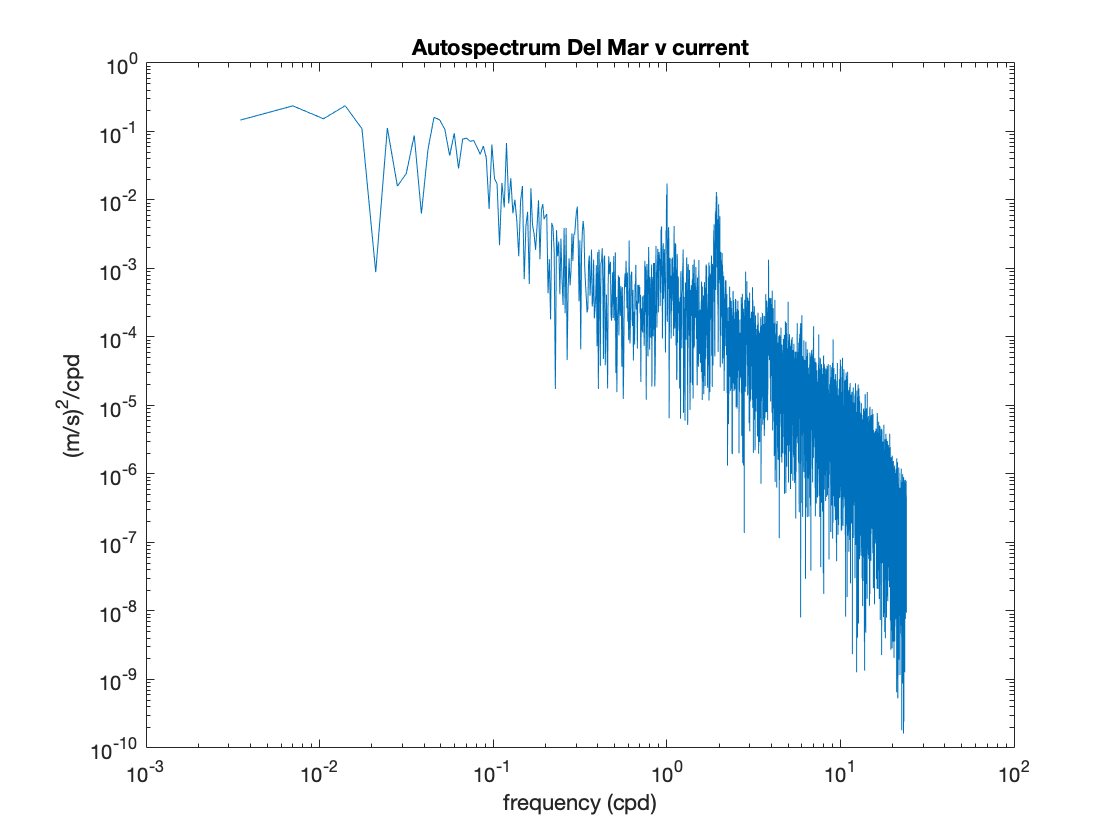

S = abs(X(2:N/2+1)).^2/N*dt;  %index 2 corresponds to 1/(N*dt), index N/2+1 to 1/(2*dt)
S(1:end-1) = 2*S(1:end-1);    %double to account for negative frequencies, except Nyqust
figure (1)
clf
loglog(f,S)
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar v current')

Frequency 10^1 to^2 .. energy with period of 10 day period 1 day period 1/10th of a day period.

Red spectrum: higher energy at lower freq, lower energy at higher freq

two peaks at 10^0 = 1 day freq, and 2 day freq, are the diurnal and semidiurnal tides

## Try different plotting options

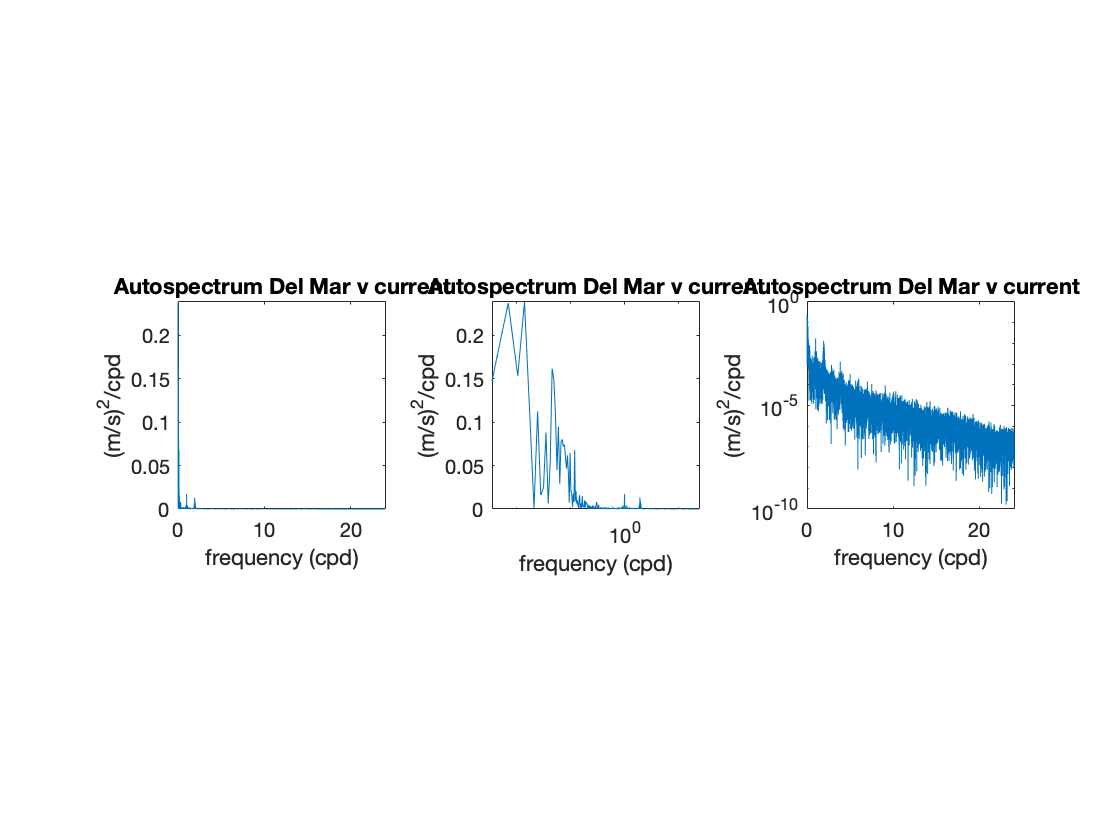

figure (2)
clf
subplot(131)
plot(f,S)
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar v current')
axis('square')
subplot(132)
semilogx(f,S)
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar v current')
axis('square')
subplot(133)
semilogy(f,S)
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar v current')
axis('square')

## S is noisy with 2 degrees of freedom at each frequency.  Smooth over adjacent frequencies 

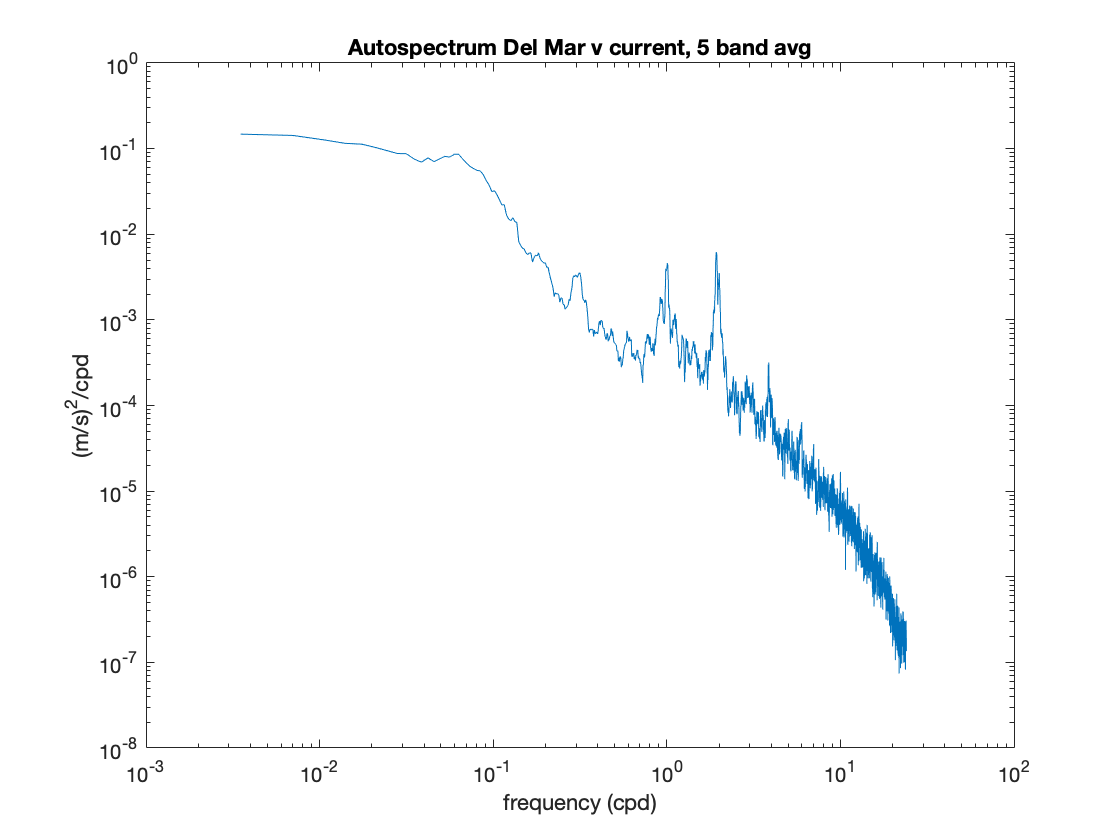

Navg = 11; 
% as we inc averaging --> less noisy but less resolution of different phenomena
% Navg controls degrees of freedom
Sm = movmean(S,Navg,'Endpoints','shrink');    %running mean, shrink reduces the averaging at the ends
figure (3)
clf
loglog(f,Sm)
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar v current, 5 band avg')

Sm = smoothed version of S ( S was pretty noisy with 2 degrees of freedom at each frequency, use a filter 

(movmean)

## Add 95% confidence interval, for plot with log10 in y axis - only need one confidence interval

clf
nu = 2*Navg;            %degrees of freedom increases with band averaging
alpha = 0.05;
ubound = nu/chi2inv(alpha/2,nu);
lbound = nu/chi2inv(1-alpha/2,nu);
figure (4)
clf
loglog(f,Sm) % periodogram
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
hold on
xb = 10;                    %specify location of confidence interval bar
yb = 1e-02;
loglog(xb,yb,'k+')  %(horizontal error bar)

alpha - probability

nu - degrees of free = 2*Navg

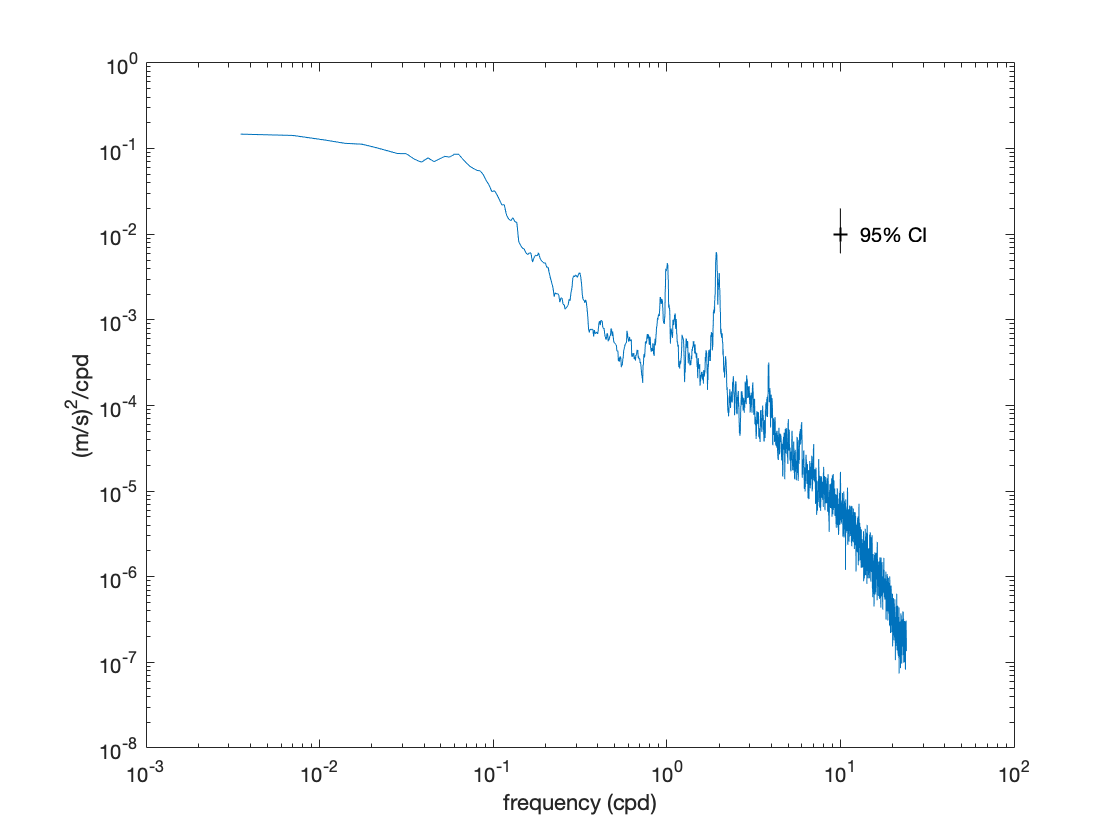

    %
loglog([xb xb],[yb*ubound yb*lbound],'k') % vertical error bar
text(xb*1.3,yb,'95% CI')

Play around with averaging to get the most out of signal (reduce noise vs keeping signal)

## Redo S with a Tukey window to reduce leakage

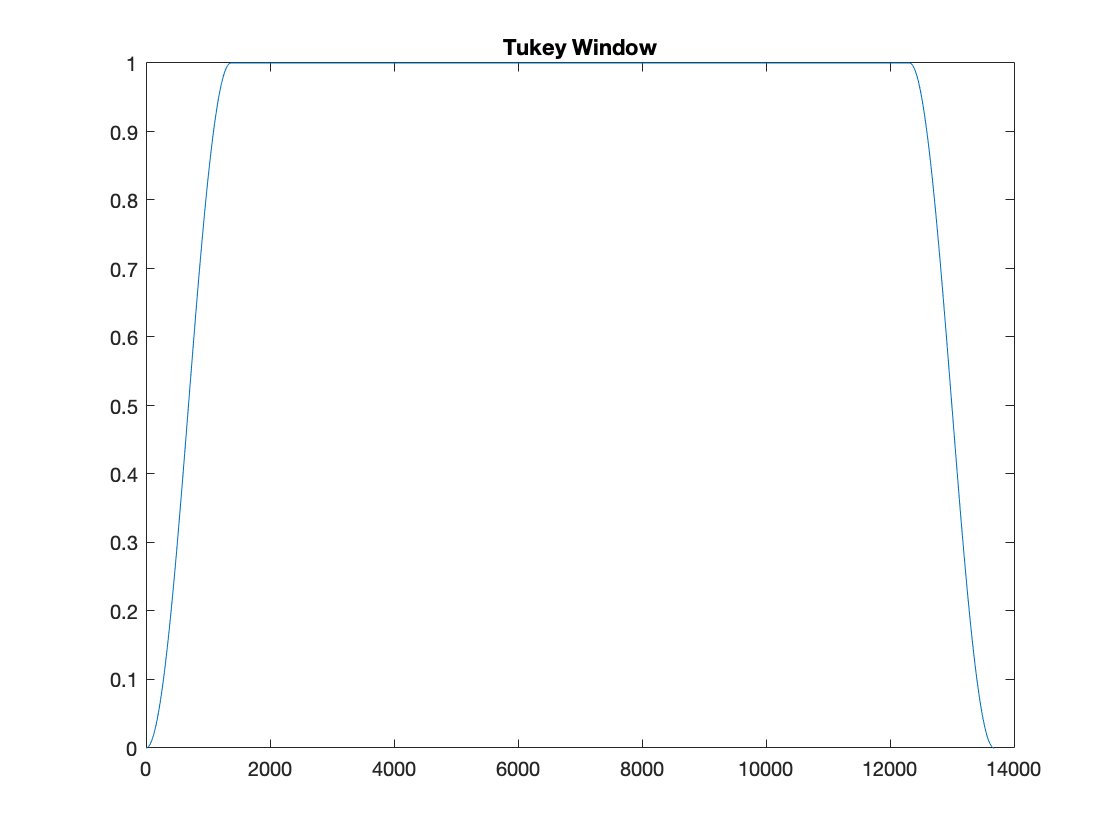

w = tukeywin(N,.2);
figure (5)
clf
plot(w)
title('Tukey Window')

Dimish amplitudes at beginning and end, using tukey window. Reduce "jumps" in record when combining end of beginning of time series.

something about combining time series in time domain is a convolution in frequency domain

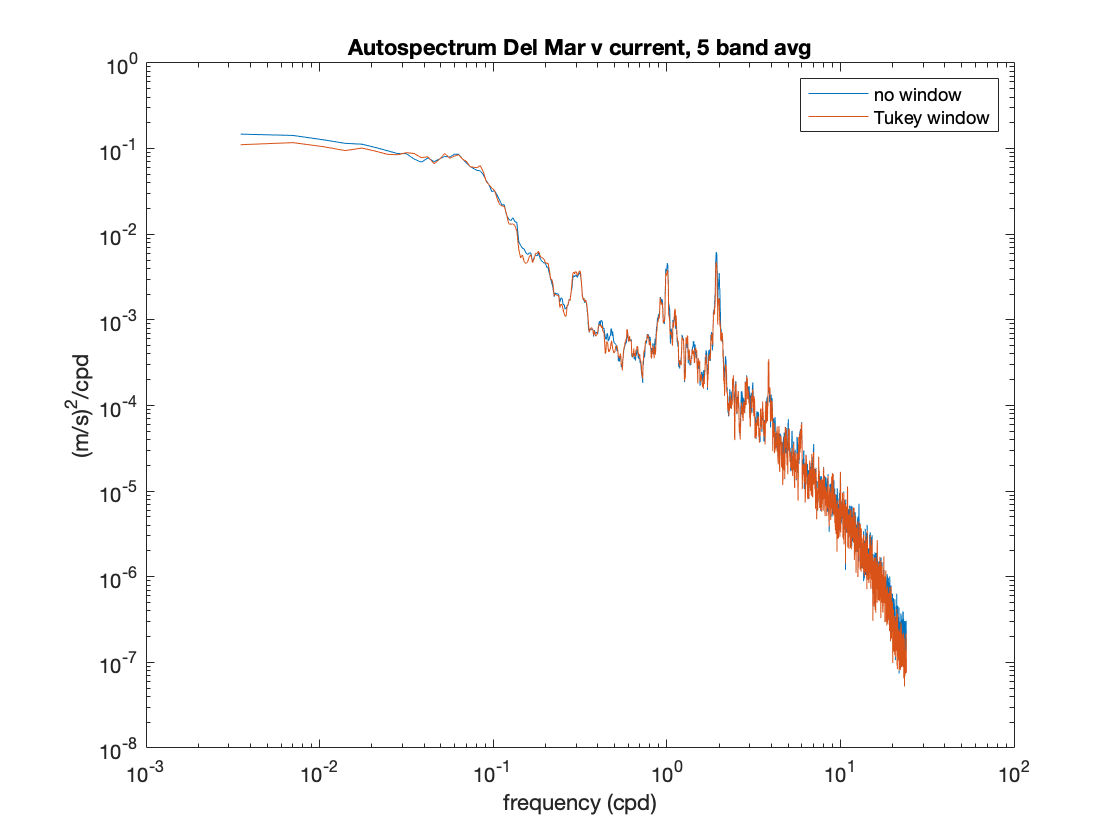

w = w/sqrt(mean(w.^2));   %scale w to account for variance reduction associated with the window
X = fft(x.*w);
S2 = abs(X(2:N/2+1)).^2/N*dt;  
S2(1:end-1) = 2*S2(1:end-1);    
S2m = movmean(S2,Navg,'Endpoints','shrink');   
figure (6)
clf
loglog(f,Sm,f,S2m)
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar v current, 5 band avg')
legend('no window','Tukey window')

## Compute autospectrum for v surface current.  Plot u and v autospectra for comparison.

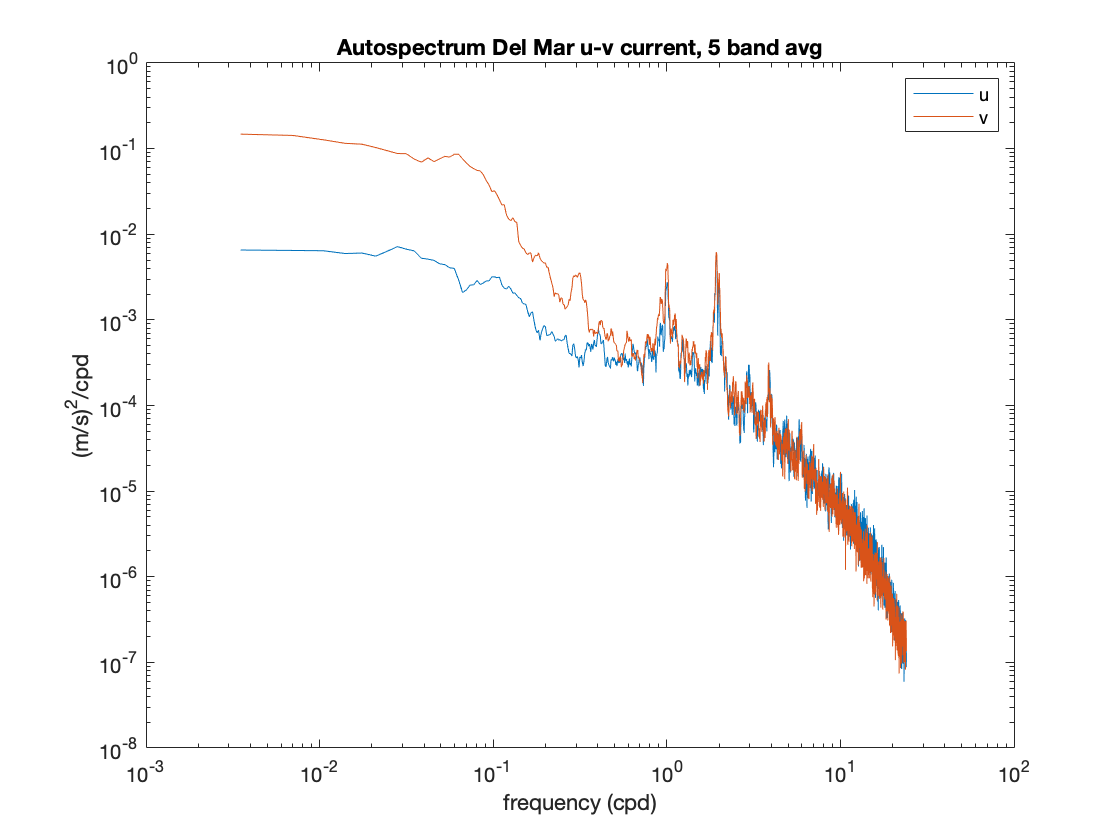

y = u(1,:)';
dt = t(2)-t(1);   %sample period in days % set units here by choosing days
N = length(t);

if(rem(N,2))
   y = y(1:end-1);
   t = t(1:end-1);
   N = N-1;
end
Y = fft(y);
f = (1:N/2)'/(N*dt);

%compute autospectrum S
S2 = abs(Y(2:N/2+1)).^2/N*dt;  %index 2 corresponds to 1/(N*dt), index N/2+1 to 1/(2*dt)
S2(1:end-1) = 2*S2(1:end-1);    %double to account for negative frequencies, except Nyqust
figure (1)
clf
% loglog(f,S2)
% xlabel('frequency (cpd)')
% ylabel('(m/s)^2/cpd')
% title('Autospectrum Del Mar u current')

% plot 
Navg = 11; 
% as we inc averaging --> less noisy but less resolution of different phenomena
% Navg controls degrees of freedom
Sm2 = movmean(S2,Navg,'Endpoints','shrink');    %running mean, shrink reduces the averaging at the ends
figure (3)
clf
loglog(f,Sm2);hold on
loglog(f,Sm)
legend('u','v')
xlabel('frequency (cpd)')
ylabel('(m/s)^2/cpd')
title('Autospectrum Del Mar u-v current, 5 band avg')

hold off

Create a function that gives back autospectrum given time series t and Navg - degrees of freedom